# Problem 1

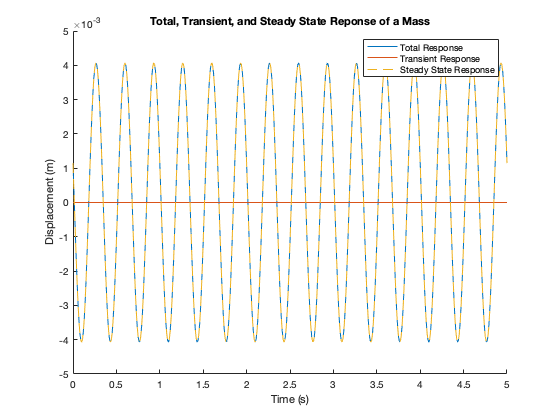

x0 = 0; v0 = 0; %initial conditions
m = 100; k = 30e3; c = 1000; F = 80; f = 3; %system parameters

wn = sqrt(k/m);
w = f * 2 * pi;
zeta = c/2/m/wn;
wd = wn * sqrt(1-zeta^2);

%Transient Response
A = (1/wd) * sqrt((v0 + zeta * wn * x0)^2 + (x0*wd)^2);

%Steady State Response
f0 = F/m;
X = f0 / sqrt((wn^2 - (w)^2)^2 + (2*zeta*wn*w)^2);
theta = atan((2*zeta*wn*w)/(wn^2 - (w)^2));

t = 0:0.01:5;
total = A * exp(-zeta .* wn .* t) .* sin(wd .* t) + X .* cos(w .* t - theta);
steady = X .* cos(w .* t - theta);
transient = A * exp(-zeta .* wn .* t) .* sin(wd .* t);

figure(1)
hold on
plot(t,total)
plot(t,transient)
plot(t,steady, '--')
legend('Total Response','Transient Response','Steady State Response');
xlabel('Time (s)');
ylabel('Displacement (m)');
title('Total, Transient, and Steady State Reponse of a Mass');

# Problem 2

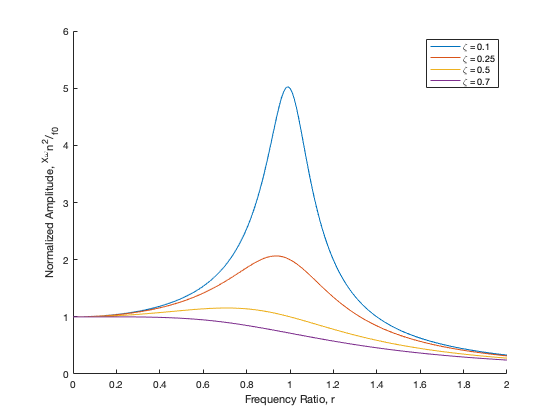

%Figure 2.8 Part A
r = 0:0.01:2;

zeta1 = 0.1;
zeta2 = 0.25;
zeta3 = 0.5;
zeta4 = 0.7;

normX1 = 1 ./ sqrt((1-r.^2).^2 + (2 .* zeta1 .* r).^2);
normX2 = 1 ./ sqrt((1-r.^2).^2 + (2 .* zeta2 .* r).^2);
normX3 = 1 ./ sqrt((1-r.^2).^2 + (2 .* zeta3 .* r).^2);
normX4 = 1 ./ sqrt((1-r.^2).^2 + (2 .* zeta4 .* r).^2);

%Frequency Ratio v. Normalized Magnitude
figure(2)
hold on
plot(r,normX1)
plot(r,normX2)
plot(r,normX3)
plot(r,normX4)
legend('\zeta = 0.1', '\zeta = 0.25', '\zeta = 0.5', '\zeta = 0.7')
ylabel('Normalized Amplitude, ^X^\omegan^2/_f_0')
xlabel('Frequency Ratio, r')

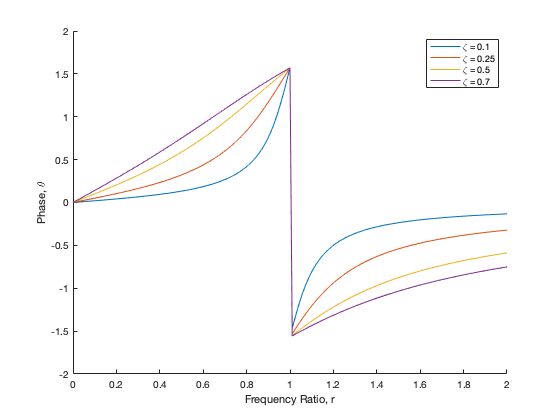


phase1 = atan((2.*zeta1.*r)./(1-(r.^2)));
phase2 = atan((2.*zeta2.*r)./(1-(r.^2)));
phase3 = atan((2.*zeta3.*r)./(1-(r.^2)));
phase4 = atan((2.*zeta4.*r)./(1-(r.^2)))

%Frequency Ratio v. Phase
figure(3)
hold on
plot(r,phase1)
plot(r,phase2)
plot(r,phase3)
plot(r,phase4)
legend('\zeta = 0.1', '\zeta = 0.25', '\zeta = 0.5', '\zeta = 0.7')
ylabel('Phase, \theta')
xlabel('Frequency Ratio, r')